# Delay Embedding and Ensemble Kalman Filtering on chaotic system

Outcomes to chaotic systems after some time become very hard to predict and being able to predict these outcomes despite the difficulty will be very useful to real life applications such as weather forecasting. The approach of neural networks was also shown in another tutorial, but here we show another brilliant way of predicitng chaos.

Clean workspace

close all; clear all; clc;

Equations that will be used:

LorenzEq = @(t, x) ([10 * (x(2) - x(1)); ...
    x(1) * (28 - x(3)) - x(2); ...
    x(1) * x(2) - (8/3) * x(3)]);

ChenEq = @(t, x) ([35 * (x(2) - x(1)); ...
    (28 - 35) * x(1) - x(1) * x(3) + 28 * x(2); ...
    x(1) * x(2) - 3 * x(3)]); 

Hyperchaotic5DEq = @(t, x) ([35 * (x(2) - x(1));
    35 * x(1) + (-5) * x(2) - x(1) * x(3) + x(5);
    -7 * x(3) + x(1) * x(1);
    10.6 * x(2) + 1 * x(4);
    -5 * x(1) - 0.05 * x(5)]);

### Delay Embedding

Delay embedding can be used to reconstruct chaotic system while preserving the properties of the system. The delayEmbedding function aims to learn the function with limited data. To do this, a [Hankel](https://en.wikipedia.org/wiki/Hankel_matrix) matrix consisting of sets of points that are shifted based on time is created. Then, singular value decomposition is performed on the matrix to obtain three matrices that may hold valuable information about the chaotic system.

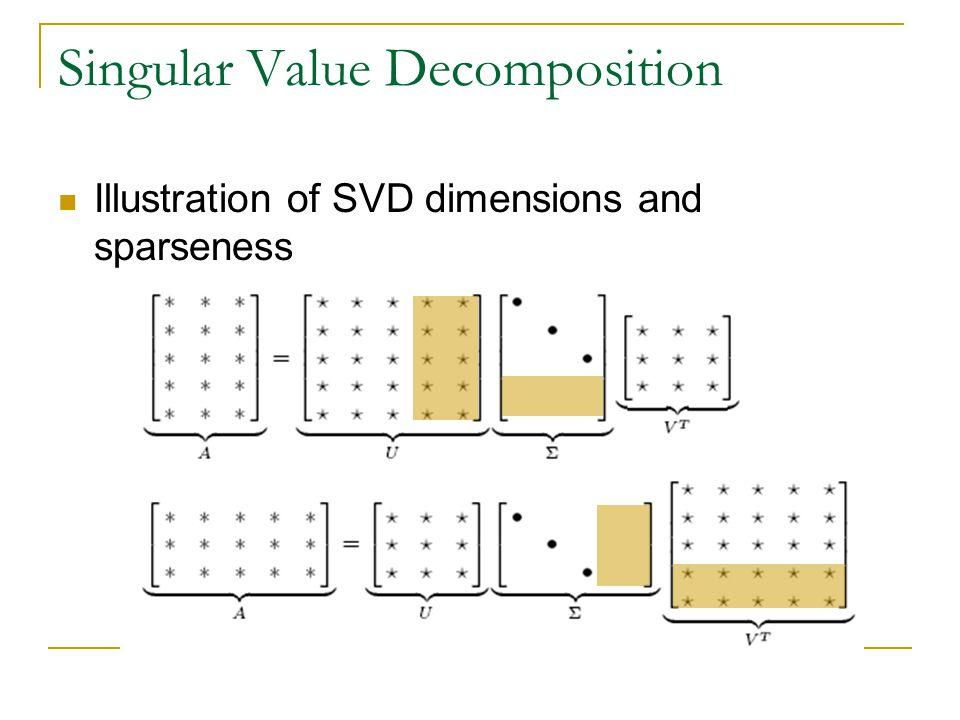

#### Hankel Matrix

%{
    hankel = [x(1:3000).'
    x(2:3001).'
    x(3:3002).'
    x(4:3003).'
    x(5:3004).'
    x(6:3005).'
    x(7:3006).'
    x(8:3007).'];
%}
    

#### Singular Value Decomposition

% [U, S, V] = svd(hankel);

#### Plots

This plots how many modes are significant to the system. For example for

the Lorenz system, you can see that there are 3 modes that have a

percentage significantly greater than 0 which means that the system is

approximately third order even if the Hankel matrix only provides x data

% 1) plot(diag(S) / (sum(diag(S))),'bo');

This is the original plot

% 2) plot3(x,y,z, 'r');

This is an inherited system based on the delay embeddings from the Hankel

Matrix, and this plot may or may not be a representation of the original

% 3) plot3(V(:, 1), V(:, 2), V(:, 3), 'k');

The tendency of a point to jump is seen in the spikes of this graph, and

this is very useful to observe the chaose in our studied system.

% 4) plot(500*V(:,4),'Linewidth',[2]);

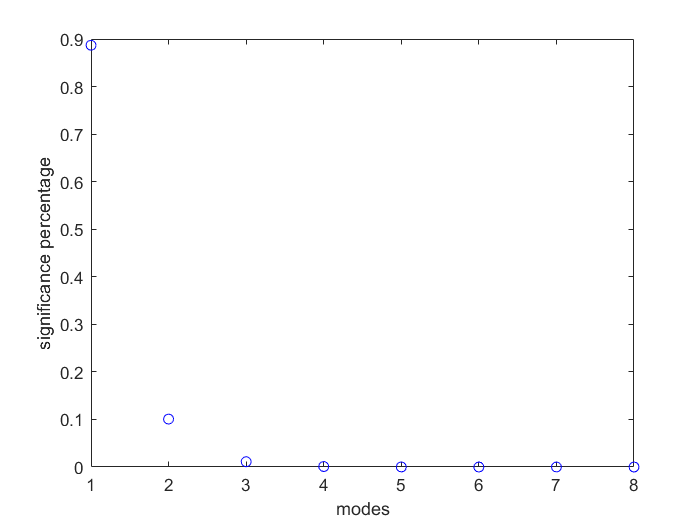

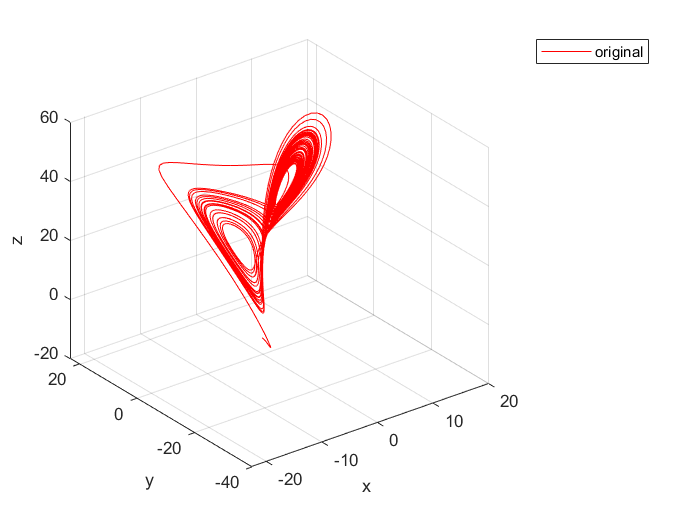

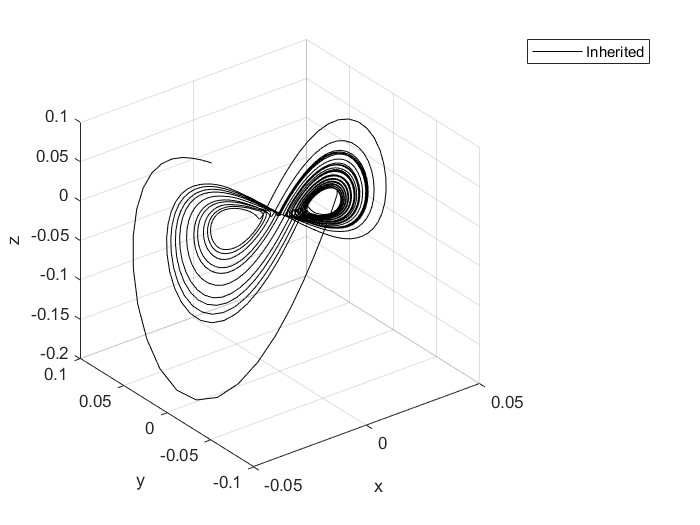

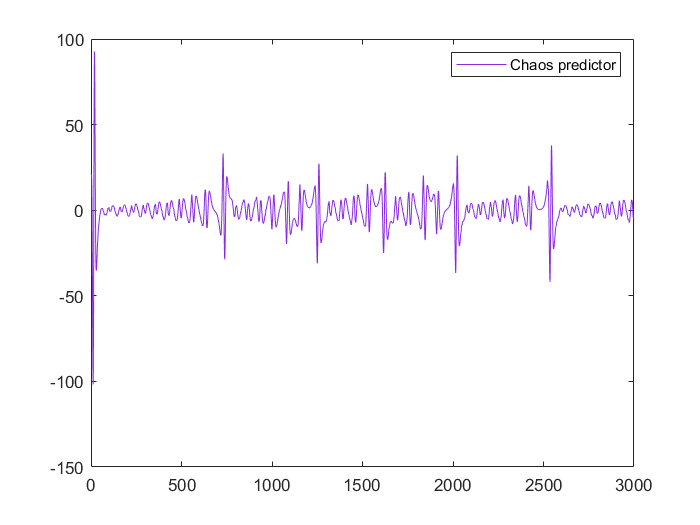

%Lorenz
delayEmbedding(LorenzEq);

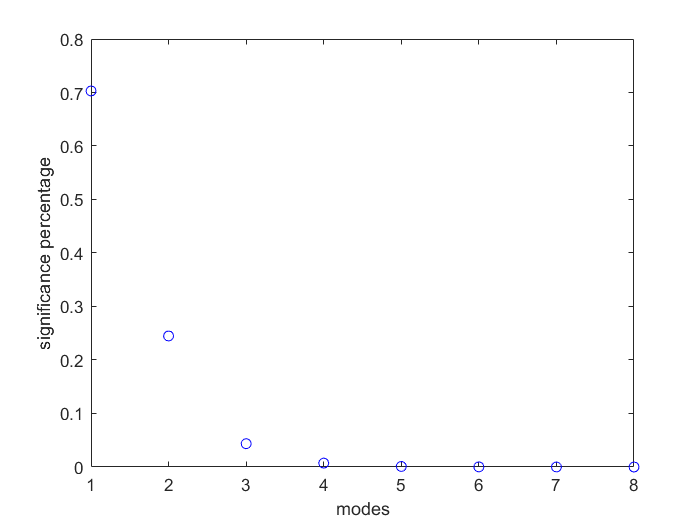

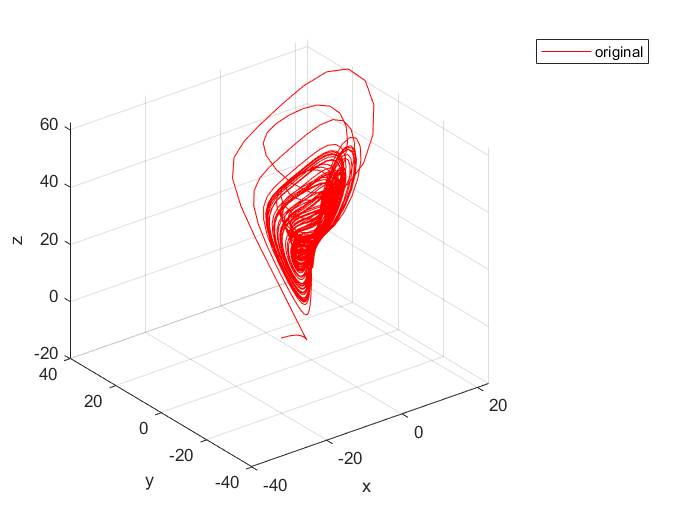

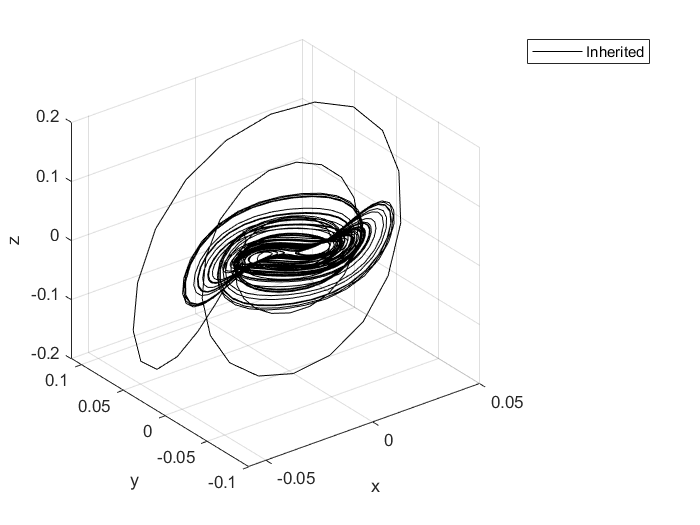

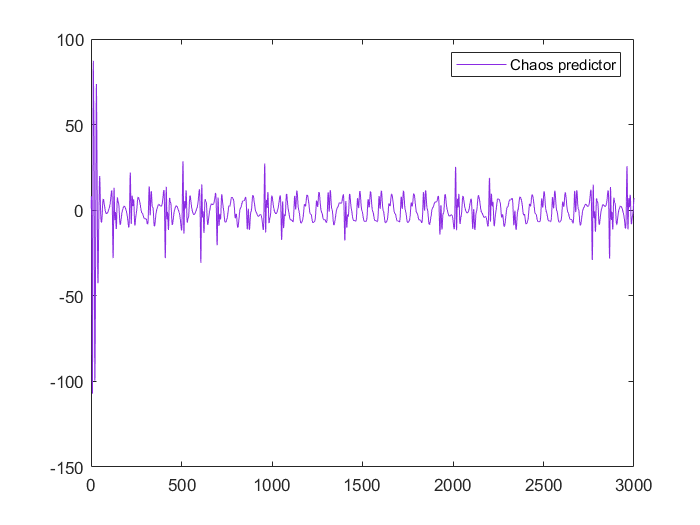

%ChenChen
delayEmbedding(ChenEq);

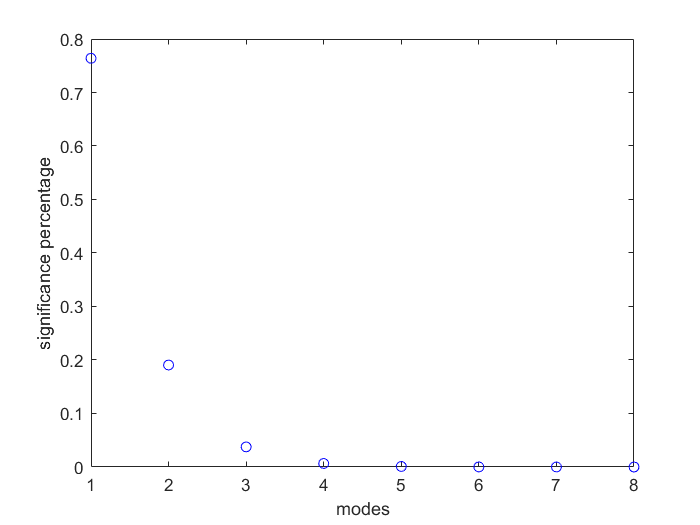

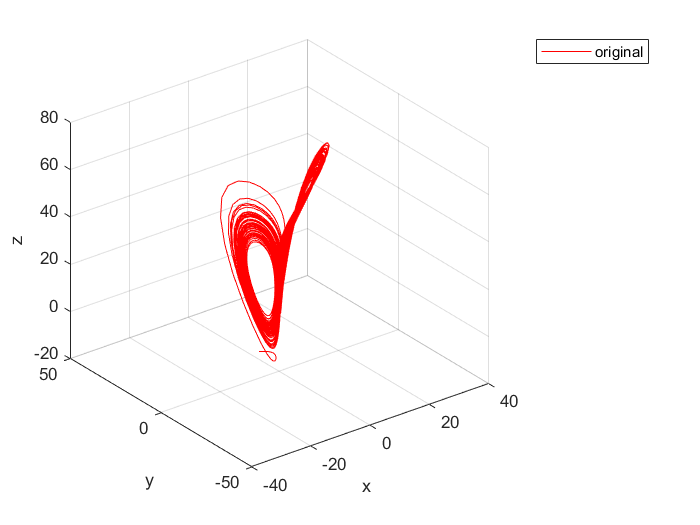

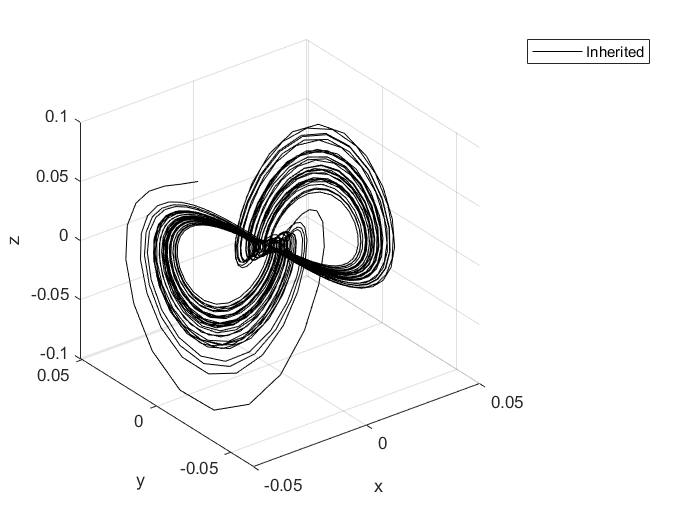

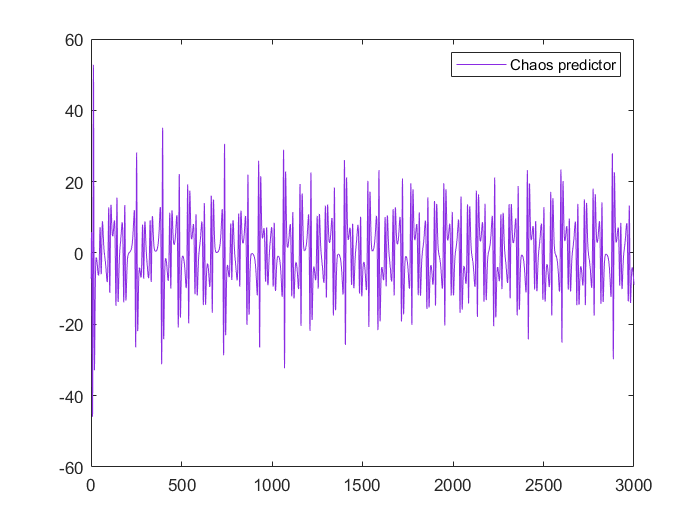

%5D Hyperchaotic
delayEmbedding5D(Hyperchaotic5DEq);

### Ensemble Kalman Filtering

Ensemble Kalman Filtering, EnKF, is a version of Kalman filtering which uses data containing noise and makes estimates of unknown parameters of the system. The problem with using Kalman filtering for our chaotic system is that there will be many instances where the result out of the Kalman filtering does not match the actual system output. We can solve this issue to an extent by using an ensemble, in this case, we will average out the different outputs based on different parameter estimations.

%{
out = [];
for i = 1: 100  
    noise = rand();
    initialCondition = [x0 y0 z0] + noise * randn(1, 3);
    tdata = time(1:50:end);
    error=rand();
    xdata = x(1:50:end) + error * randn(length(tdata), 1);
    ydata = y(1:50:end) + error * randn(length(tdata), 1);
    zdata = z(1:50:end) + error * randn(length(tdata), 1);

    curr = [];
    for j = 1:length(tdata)-1
        t = 0:0.01:0.5;
        [t, xyz] = ode45(handler, t, initialCondition);
        initialCondition0 = [xyz(end,1); xyz(end,2); xyz(end,3)];
        data = [xdata(j+1); ydata(j+1); zdata(j+1)];
        kalmanFilter = noise/ (noise + error);
        initialCondition = initialCondition0 + (kalmanFilter * (data - initialCondition0));
        curr = [curr; xyz(1:end-1,:)];
    end
    curr = [curr; xyz(end,:)];
    out(:, :, i) = curr;
end
out = mean(out, 3);
%}

The Ensemble Kalman Filtering function, EnKF contains two for loops: the inner loop mainly as the Kalman filtering and the outer loop as making the ensembles. There is a noise variable which contributes to the variance matrix in the Kalman Filter equation. There is also an error variable which with the noise is useful in studying the dynamics of the system. The kalman filter used in this program is the ratio between the noise and the sum of the noise and error.At the end of the nested for loop, the avarage of the results was computed.

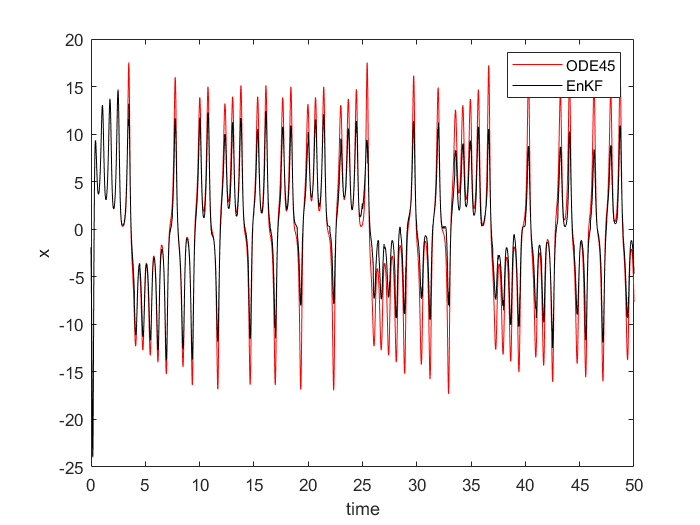

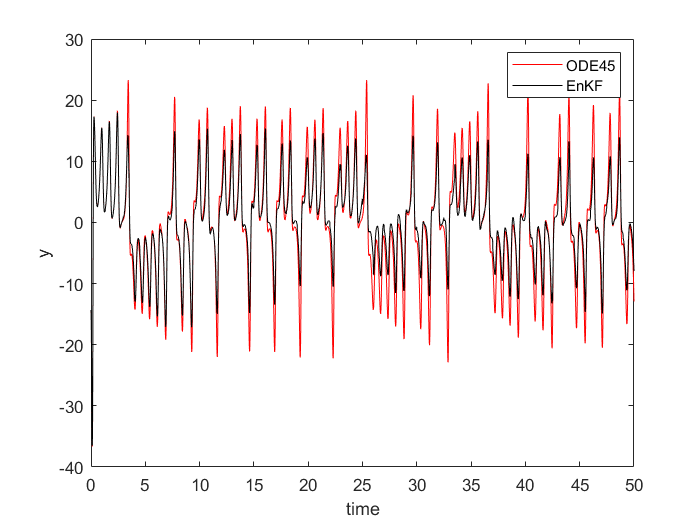

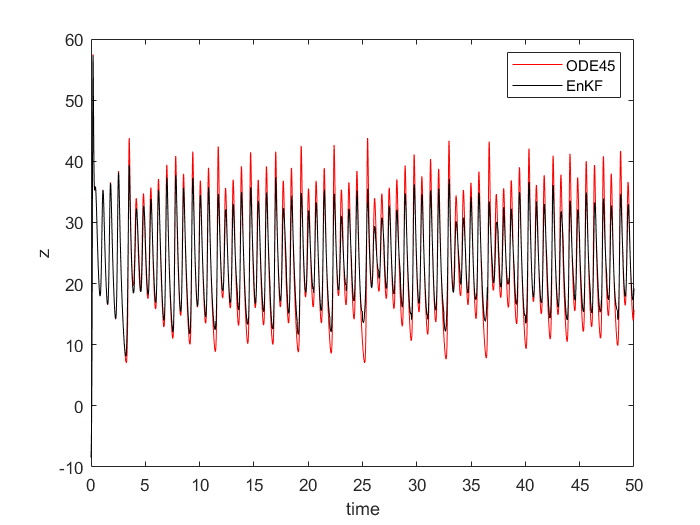

%Lorenz
EnKF(LorenzEq);

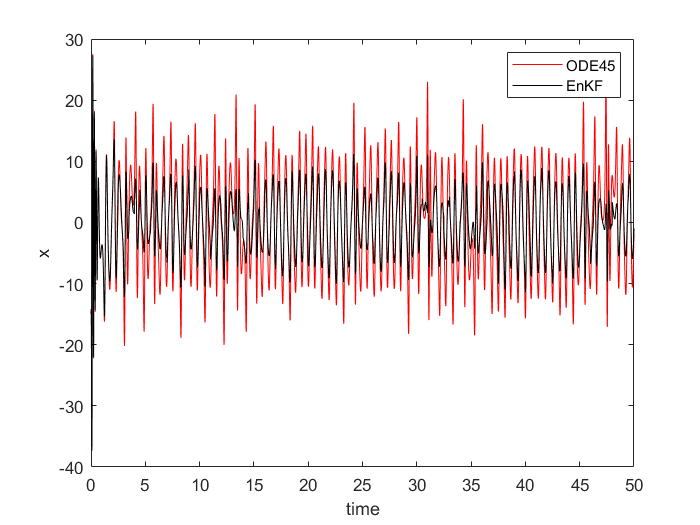

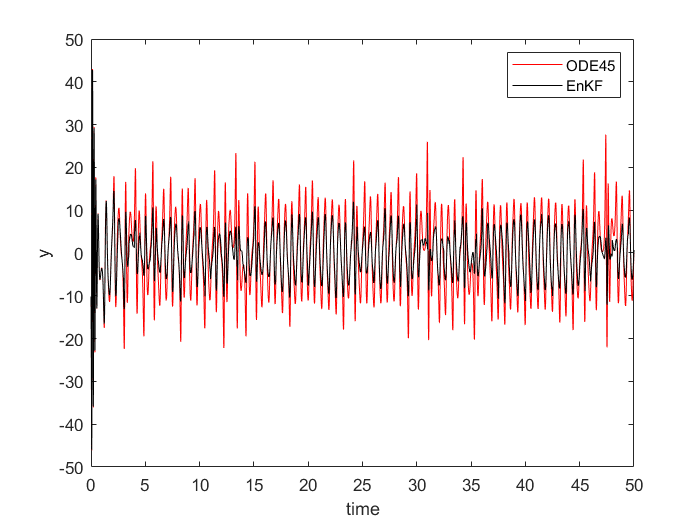

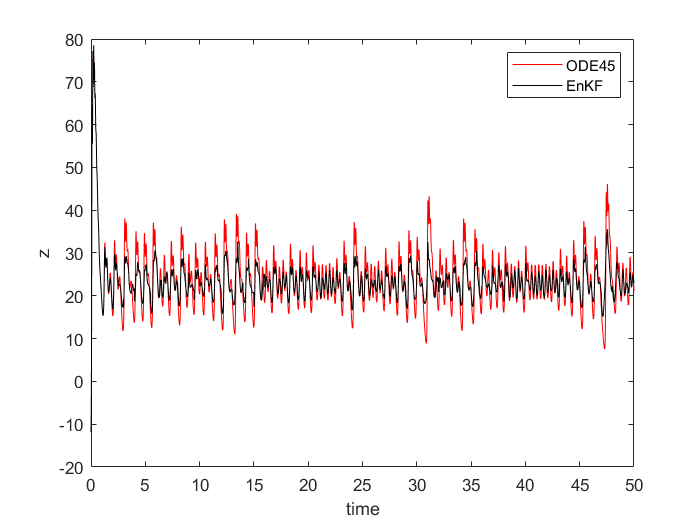

%Chen
EnKF(ChenEq);

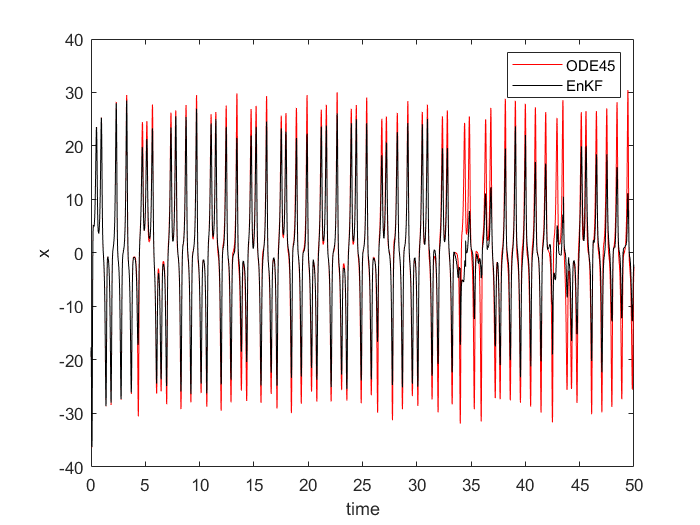

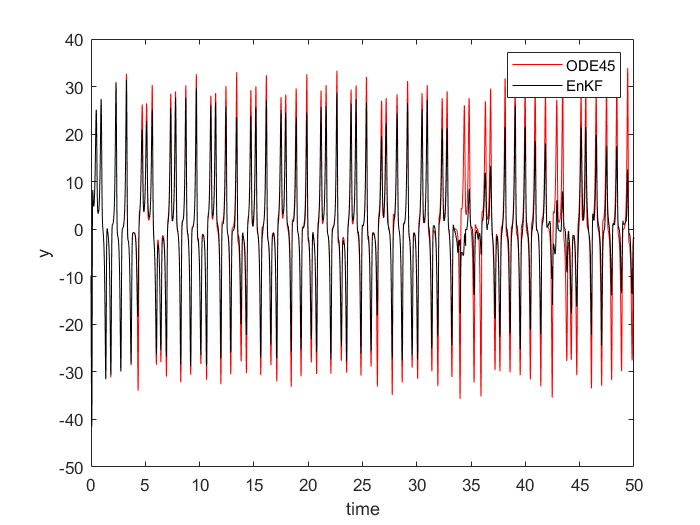

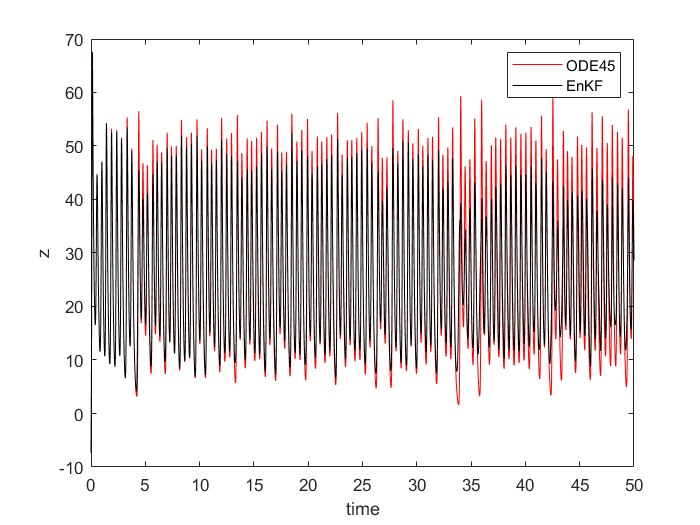

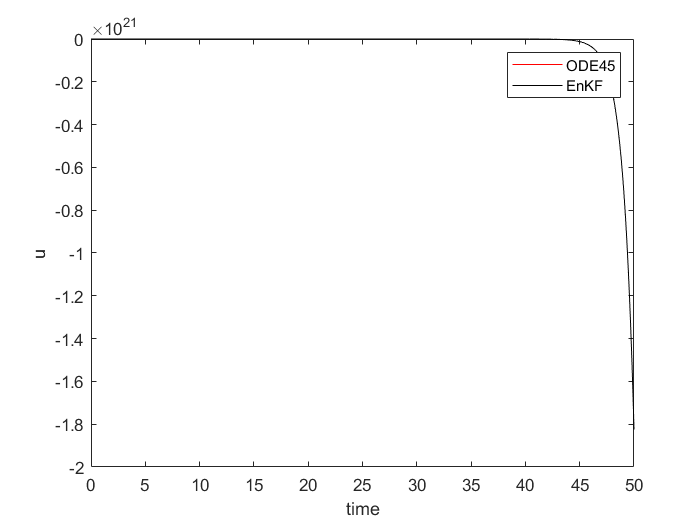

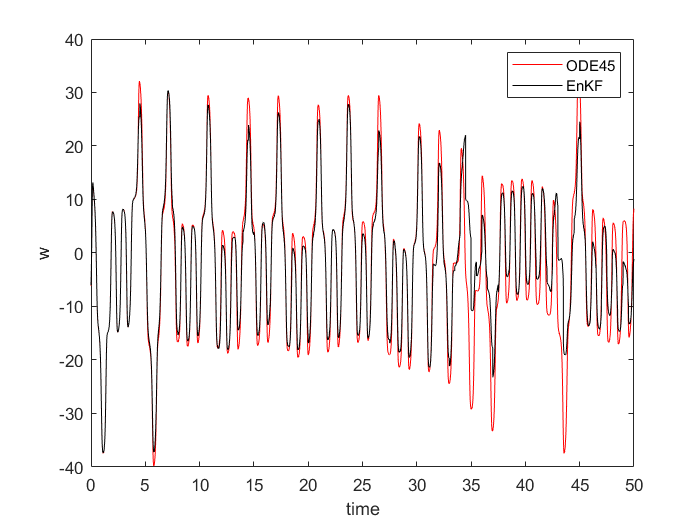

%5D Hyperchaotic
EnKF5D(Hyperchaotic5DEq);

### Helper Functions

function [] = EnKF(handler)
dt = .01;
totalTime = 50;
time = 0:dt:totalTime;
x0 = 20 * (rand - 1);
y0 = 20 * (rand - 1);
z0 = 20 * (rand - 1);
[time, triple] = ode45(handler, time, [x0; y0; z0]);
x = triple(:, 1);
y = triple(:, 2);
z = triple(:, 3);

out = [];
for i = 1: 100
    noise = rand();
    initialCondition = [x0 y0 z0] + noise * randn(1, 3);
    tdata = time(1:50:end);
    error=rand();
    xdata = x(1:50:end) + error * randn(length(tdata), 1);
    ydata = y(1:50:end) + error * randn(length(tdata), 1);
    zdata = z(1:50:end) + error * randn(length(tdata), 1);

    curr = [];
    for j = 1:length(tdata)-1
        t = 0:0.01:0.5;
        [t, xyz] = ode45(handler, t, initialCondition);
        initialCondition0 = [xyz(end,1); xyz(end,2); xyz(end,3)];
        data = [xdata(j+1); ydata(j+1); zdata(j+1)];
        kalmanFilter = noise/ (noise + error);
        initialCondition = initialCondition0 + (kalmanFilter * (data - initialCondition0));
        curr = [curr; xyz(1:end-1,:)];
    end
    curr = [curr; xyz(end,:)];
    out(:, :, i) = curr;
end
out = mean(out, 3);

figure(1);
plot(time, x,'r',time, out(:,1),'k');
xlabel('time');
ylabel('x');
legend('ODE45','EnKF');

figure(2);
plot(time, y,'r',time, out(:,2),'k');
xlabel('time');
ylabel('y');
legend('ODE45','EnKF');

figure(3);
plot(time, z,'r',time, out(:,3),'k');
xlabel('time');
ylabel('z');
legend('ODE45','EnKF');
end

function [] = delayEmbedding(handler)
dt = .01;
totalTime = 50;
time = 0:dt:totalTime;
x0 = 20 * (rand - 1);
y0 = 20 * (rand - 1);
z0 = 20 * (rand - 1);
[time, triple] = ode45(handler,time, [x0; y0; z0]);
x = triple(:, 1);
y = triple(:, 2);
z = triple(:, 3);

hankel = [x(1:3000).'
        x(2:3001).'
        x(3:3002).'
        x(4:3003).'
        x(5:3004).'
        x(6:3005).'
        x(7:3006).'
        x(8:3007).'];
    
[U, S, V] = svd(hankel);

figure(2);
plot(diag(S) / (sum(diag(S))),'bo');
xlabel('modes');
ylabel('significance percentage');

figure(3);
plot3(x,y,z, 'r');
grid on;
xlabel('x');
ylabel('y');
zlabel('z');
legend('original');

figure(4);
plot3(V(:, 1), V(:, 2), V(:, 3), 'k');
grid on;
xlabel('x');
ylabel('y');
zlabel('z');
legend('Inherited');

figure(5);
plot(500*V(:,4), 'Color', [0.54, 0.17, 0.89]);
legend('Chaos predictor');
end

function [] = EnKF5D(handler)
dt = .01;
totalTime = 50;
time = 0:dt:totalTime;
x0 = 20 * (rand - 1);
y0 = 20 * (rand - 1);
z0 = 20 * (rand - 1);
u0 = 20 * (rand - 1);
w0 = 20 * (rand - 1);
[time, five] = ode45(handler,time, [x0; y0; z0; u0; w0]);
x = five(:, 1);
y = five(:, 2);
z = five(:, 3);
u = five(:, 4);
w = five(:, 5);

out = [];
for i = 1: 100
    noise = rand();
    initialCondition = [x0 y0 z0 u0 w0] + noise * randn(1, 5);
    tdata = time(1:50:end);
    error=rand();
    xdata = x(1:50:end) + error * randn(length(tdata), 1);
    ydata = y(1:50:end) + error * randn(length(tdata), 1);
    zdata = z(1:50:end) + error * randn(length(tdata), 1);
    udata = u(1:50:end) + error * randn(length(tdata), 1);
    wdata = w(1:50:end) + error * randn(length(tdata), 1);

    curr = [];
    for j = 1:length(tdata)-1
        t = 0:0.01:0.5;
        [t, xyz] = ode45(handler, t, initialCondition);
        initialCondition0 = [xyz(end,1); xyz(end,2); xyz(end,3); xyz(end,4); xyz(end,5)];
        data = [xdata(j+1); ydata(j+1); zdata(j+1); udata(j+1); wdata(j+1)];
        kalmanFilter = noise/ (noise + error);
        initialCondition = initialCondition0 + (kalmanFilter * (data - initialCondition0));
        curr = [curr; xyz(1:end-1,:)];
    end
    curr = [curr; xyz(end,:)];
    out(:, :, i) = curr;
end
out = mean(out, 3);

figure(1);
plot(time, x,'r',time, out(:,1),'k');
xlabel('time');
ylabel('x');
legend('ODE45','EnKF');

figure(2);
plot(time, y,'r',time, out(:,2),'k');
xlabel('time');
ylabel('y');
legend('ODE45','EnKF');

figure(3);
plot(time, z,'r',time, out(:,3),'k');
xlabel('time');
ylabel('z');
legend('ODE45','EnKF');

figure(4);
plot(time, u,'r',time, out(:,4),'k');
xlabel('time');
ylabel('u');
legend('ODE45','EnKF');

figure(5);
plot(time, w,'r',time, out(:,5),'k');
xlabel('time');
ylabel('w');
legend('ODE45','EnKF');
end

function [] = delayEmbedding5D(handler)
dt = .01;
totalTime = 50;
time = 0:dt:totalTime;
x0 = 20 * (rand - 1);
y0 = 20 * (rand - 1);
z0 = 20 * (rand - 1);
u0 = 20 * (rand - 1);
w0 = 20 * (rand - 1);
[time, five] = ode45(handler,time, [x0; y0; z0; u0; w0]);
x = five(:, 1);
y = five(:, 2);
z = five(:, 3);
u = five(:, 4);
w = five(:, 5);

hankel = [x(1:3000).'
        x(2:3001).'
        x(3:3002).'
        x(4:3003).'
        x(5:3004).'
        x(6:3005).'
        x(7:3006).'
        x(8:3007).'];
    
[U, S, V] = svd(hankel);

figure(2);
plot(diag(S) / (sum(diag(S))),'bo');
xlabel('modes');
ylabel('significance percentage');

figure(3);
plot3(x,y,z, 'r');
grid on;
xlabel('x');
ylabel('y');
zlabel('z');
legend('original');

figure(4);
plot3(V(:, 1), V(:, 2), V(:, 3), 'k');
grid on;
xlabel('x');
ylabel('y');
zlabel('z');
legend('Inherited');

figure(5);
plot(500*V(:,4), 'Color', [0.54, 0.17, 0.89]);
legend('Chaos predictor');
end
